# Parabolic Equation  - **Implicit** solution (Finite Difference)

Consider the following problem:

- 
$$k\ldotp \frac{\partial^{\;2} T}{\partial x^2 }\;\;\;=\;\frac{\partial T}{\partial t}$$


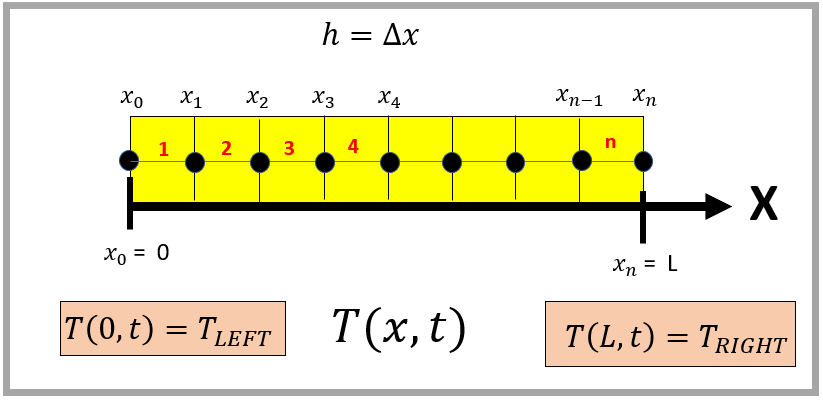

**History:**

- `Apr-2021 : Created(bhorton@mathworks.com)`

## Prework:

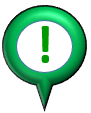 **ATTENTION: ** Before starting this tutorial, have a look at the short(VERY !) script called [`bh_pre_work_table_essentials.mlx`](matlab:  edit bh_pre_work_table_essentials.mlx) - it introduces a sata container called a **table**. The **table** data type is SUPER convenient for assembling the system matrices that we'll encounter in THIS case study !

## The design task:

Finite difference for the heat conduction equation

clc 
clear

**Define the Boundary Conditions**

- 
$$T\left(0,t\right)=80;$$


- 
$$T\left(L,t\right)=30;$$


BC_T0 = @(t) 80;  % LEFT side
BC_TL = @(t) 30;  % RIGHT side 

**Define the Initial Conditions**

- 
$$T\left(x,0\right)=30\ldotp \sin \left(8\ldotp 3776\ldotp x\right)\;\;-\;33\ldotp 33\ldotp x\;\;+\;\;80$$


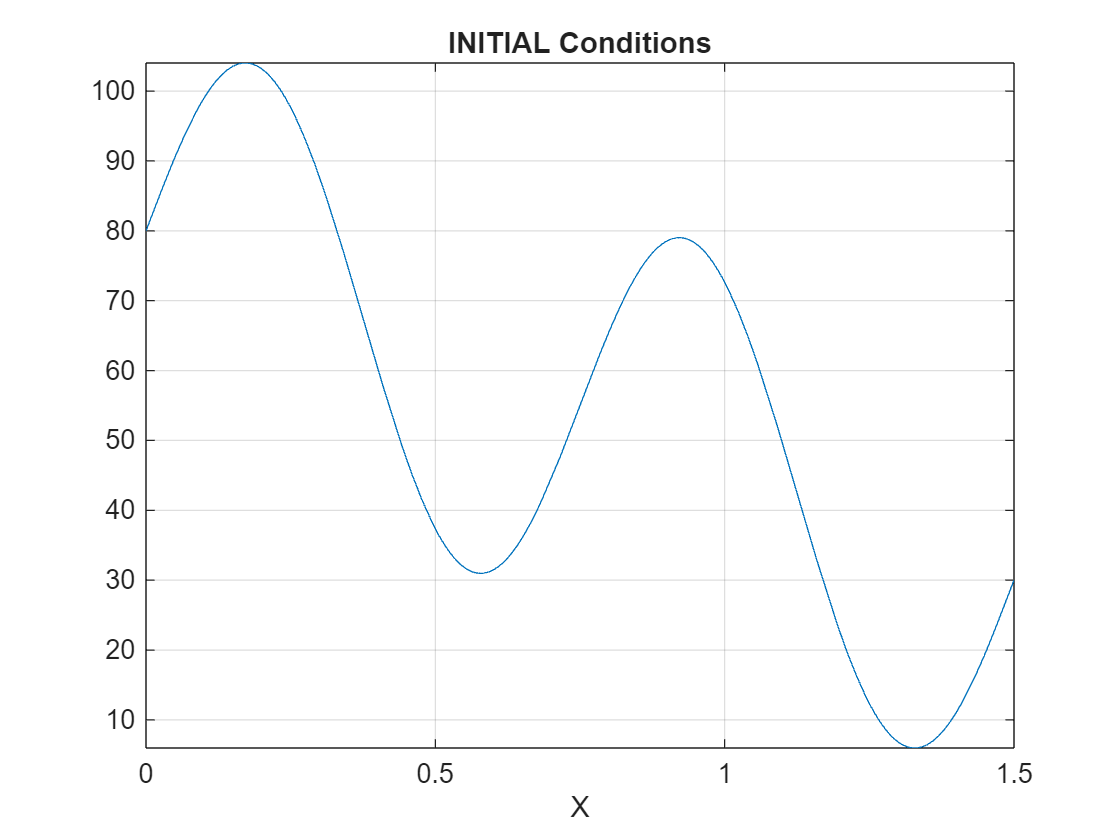

IC_Tz = @(x) 30*sin(8.3776*x) - 33.3333*x + 80; 

figure;
    fplot(IC_Tz, [0, 1.5]);  
        grid("on"); xlabel("X"); title("INITIAL Conditions")

 NOTE:  the consistency with our BOUNDARY conditions

[ IC_Tz(0),  IC_Tz(1.5) ]    

ans =    80.0000   30.0009


**Define the spatial Grid**

n  = 50;   % NUM intervals in space
L   = 1.5;
h  = L/n;                    % SPATIAL step size

x   = linspace(0 ,L, n + 1); % to generate equally spaced (n + 1) points
Npt = n + 1;

**Define the time step and LAMBDA**

dt                         = 0.1;                   % time step size
n_time_intervals           = 600;                   % number of time steps to DO
animation_plot_interval    = 10;                   % interval between each figure plot for animation
Ntime_pts                  = 1 + n_time_intervals;
K                          = 0.78/700;  
lambda                     = K*dt/h^2;

### Our Problem formulation:

Consider the simple grid shown below

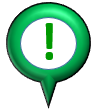 **ATTENTION: ** ****** STENCIL DERIVATION ******

- The Derivation for our Finite Difference IMPLICIT stencil is in the file [`bh_deriv_for_1d_pde_para_heat_trans_implicit.mlx`](matlab:  edit bh_deriv_for_1d_pde_para_heat_trans_implicit.mlx)

For this simple grid, we have a series of grid points .... which we'll call **NODES**.  For each NODE, observe the following:

- A NODE has an ID - say $i$

- A NODE has an X co-ordinate $\left(x_i \;\right)$

- At time $t=t_{\theta }$ a NODE $i$ has a Temperature  $T_i^{\theta }$

- Two NODES are BOUNDARY condition nodes - we already know the temperatures at these nodes !

- The remaining NODES are INTERNAL nodes - so we can write out the **implicit** Finite Difference stencil for these nodes

At time  $t=t_{\theta }$, we can write for each NODE:

-  the **Implicit** Finite Difference stencil      $-\lambda \ldotp T_{i-1}^{\theta +1} \;\;+\;\;\left(1+2\lambda \right)\ldotp T_i^{\theta +1} \;\;-\;\;\lambda \ldotp T_{i+1}^{\theta +1} \;\;=\;\;T_i^{\theta } \;\;\;$

- **OR** we can write out the known temperature, because the NODE is at a boundary condition

- NOTE:  the **derivation** of the stencil equation is in [`bh_deriv_for_1d_pde_para_heat_trans_implicit.mlx`](matlab:  edit bh_deriv_for_1d_pde_para_heat_trans_implicit.mlx)

We can then collect/organise these equations in MATRIX form.  The MATRIX form of our system will have the shape: 

-   
$$A\;\ldotp z=b$$
 

where:

- $A\left(\lambda \right)$  **NOTE: ** the $A$ matrix is INDEPENDENT of time

- 
$$\textrm{transpose}\left(z\right)=\left\lbrack T_0^{\theta +1} \;\;\;T_1^{\theta +1} \;\;\;T_2^{\theta +1} \;\;\;T_3^{\theta +1} \;\;\;T_4^{\theta +1} \;\;\;T_5^{\theta +1} \;\cdots \cdots \;T_n^{\theta +1} \right\rbrack \;$$


- 
$$\textrm{transpose}\left(b\right)=\left\lbrack T_0^{\theta } \;\;\;T_1^{\theta } \;\;\;T_2^{\theta } \;\;\;T_3^{\theta } \;\;\;T_4^{\theta } \;\;\;T_5^{\theta } \;\cdots \cdots \;T_n^{\theta } \right\rbrack \;$$


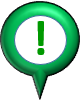 **NOTE:**  by solving this system of linear simultaneous equations we are able to compute $T_i^{\theta +1}$   , ie:  we can **STEP** (or advance) the dynamics forward in time.  So the workflow for solving this problem can be broken down into 2 main steps, as shown below:

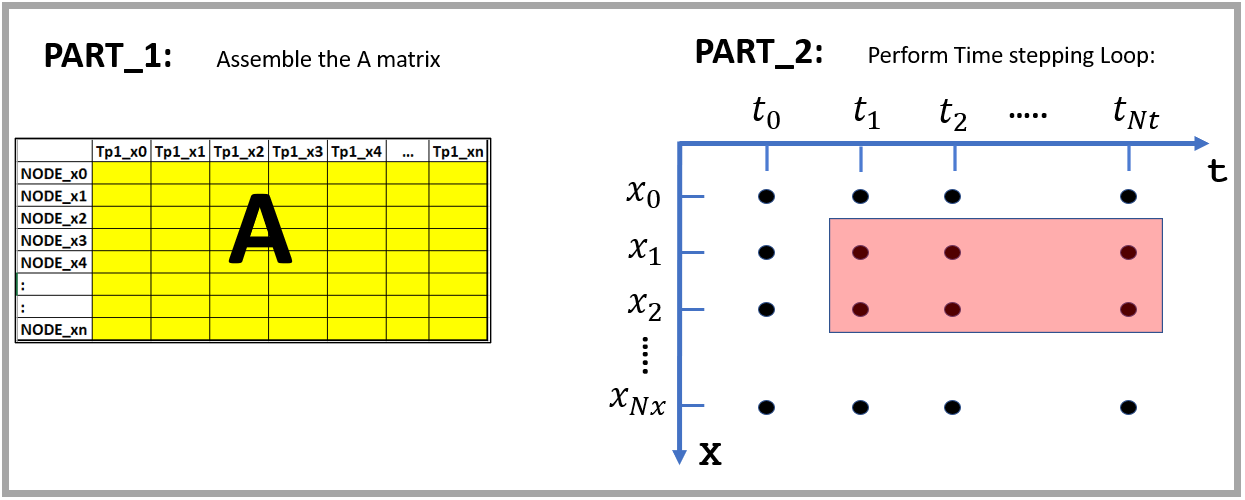

To help with the "book keeping" of assembling our system A matrix, let's use TABLES.  We'll label our columns and we'll label our rows.

- The ROW labels will take the form:  `NODE_i`

- The COLUMN labels will take the form:  `Tp1_i `which represents $T_i^{\theta +1}$

## PART_1 implementation:    Assemble A matrix

NODE_name_list = "NODE_x" + (0:(Npt-1));  %    row labels for the A table
T_name_list    =  "Tp1_x" + (0:(Npt-1));  % column labels for the A table

Our Table is initially populated with ZERO values:

A_TAB   = array2table(zeros(Npt, Npt), "RowNames",NODE_name_list, "VariableNames",  T_name_list);

OK:  populate the A table according to our stencil:

-  INTERNAL NODES:                         $-\lambda \ldotp T_{i-1}^{\theta +1} \;\;+\;\;\left(1+2\lambda \right)\ldotp T_i^{\theta +1} \;\;-\;\;\lambda \ldotp T_{i+1}^{\theta +1} \;$

- BOUNDARY Condition NODES:         $T_i^{\theta +1} \;\;=\;\;T_i^{\theta }$

for xx_ID=0:(Npt-1)
        
    if(          0==xx_ID),   NODE_TYPE = "BC_LEFT";
    elseif((Npt-1)==xx_ID),   NODE_TYPE = "BC_RIGHT";
    else,                     NODE_TYPE = "INTERNAL"; 
    end    
    
    NODE_ID_str = "NODE_x"  + xx_ID;
        
    % now process the node
    switch(NODE_TYPE)         
        case "BC_LEFT"
                         A_TAB{NODE_ID_str, ("Tp1_x"  + (xx_ID))  } =  1;            
        case "BC_RIGHT"
                         A_TAB{NODE_ID_str, ("Tp1_x"  + (xx_ID))  } =  1;                      
        case "INTERNAL"                        
                         A_TAB{NODE_ID_str, ("Tp1_x"  + (xx_ID-1))} =     -1*lambda;
                         A_TAB{NODE_ID_str, ("Tp1_x"  + (xx_ID))  } =  1 + 2*lambda; 
                         A_TAB{NODE_ID_str, ("Tp1_x"  + (xx_ID+1))} =     -1*lambda;        
        otherwise
            error("###_ERROR:  Bad !")
    end    
    
end % for xx_ID

 Let's have a look at our **A** table        

A_TAB = 51×51 table
                 Tp1_x0      Tp1_x1      Tp1_x2      Tp1_x3      Tp1_x4      Tp1_x5      Tp1_x6      Tp1_x7      Tp1_x8      Tp1_x9     Tp1_x10     Tp1_x11     Tp1_x12     Tp1_x13     Tp1_x14     Tp1_x15     Tp1_x16     Tp1_x17    Tp1_x18    Tp1_x19    Tp1_x20    Tp1_x21    Tp1_x22    Tp1_x23    Tp1_x24    Tp1_x25    Tp1_x26    Tp1_x27    Tp1_x28    Tp1_x29    Tp1_x30    Tp1_x31    Tp1_x32    Tp1_x33

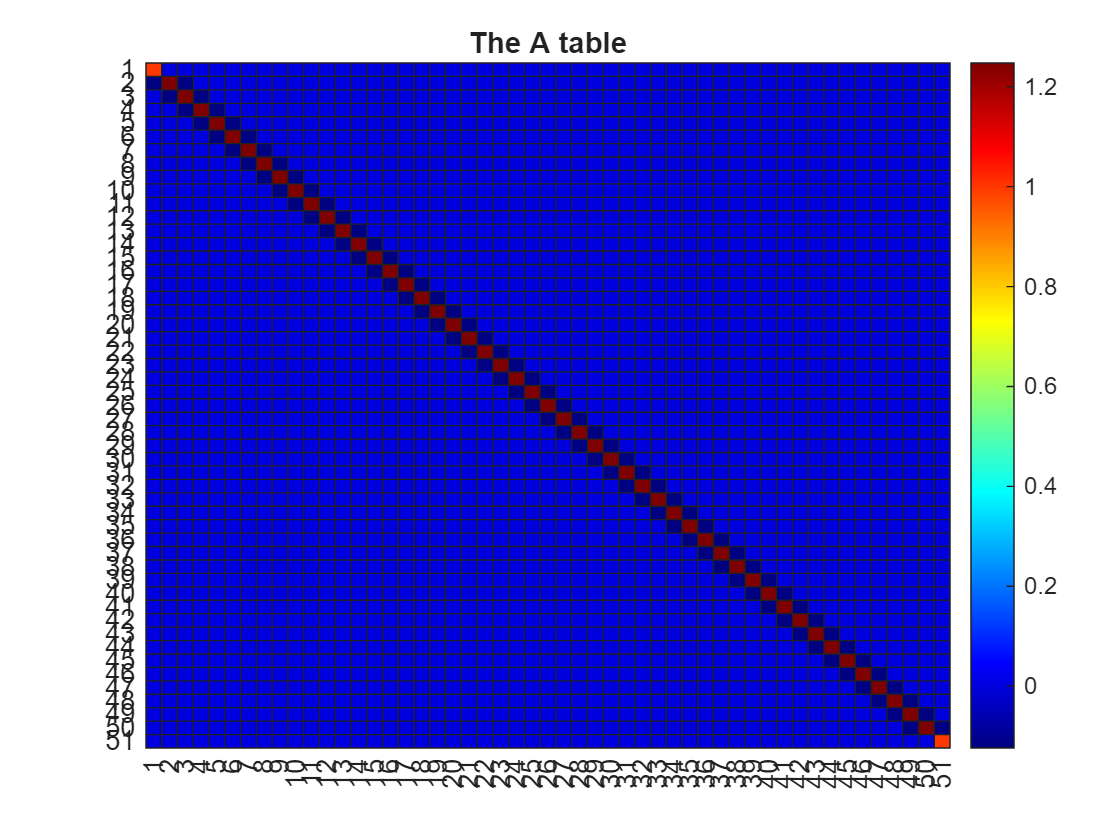

if(Npt<=11)
    
    A_TAB
    
    % the heatmap() function will apply LaTex interpretation to the ROW,COL strings
    no_subs_NODE_name_list = replace(NODE_name_list, "_", "\_");
    no_subs_T_name_list    = replace(T_name_list   , "_", "\_");
    
    figure;
        h1 = heatmap(no_subs_T_name_list, no_subs_NODE_name_list, A_TAB{:,:} ); colormap(jet)
                title("The A table")
    
else
    A_TAB  % just echo the table 
         
    figure;       
        heatmap( A_TAB{:,:} ); 
            colormap(jet); 
            title("The A table")
end           

## PART_2 implementation:    Time stepping

OK, now we need to perform the time stepping part:

#### Set up our results temperature matrix

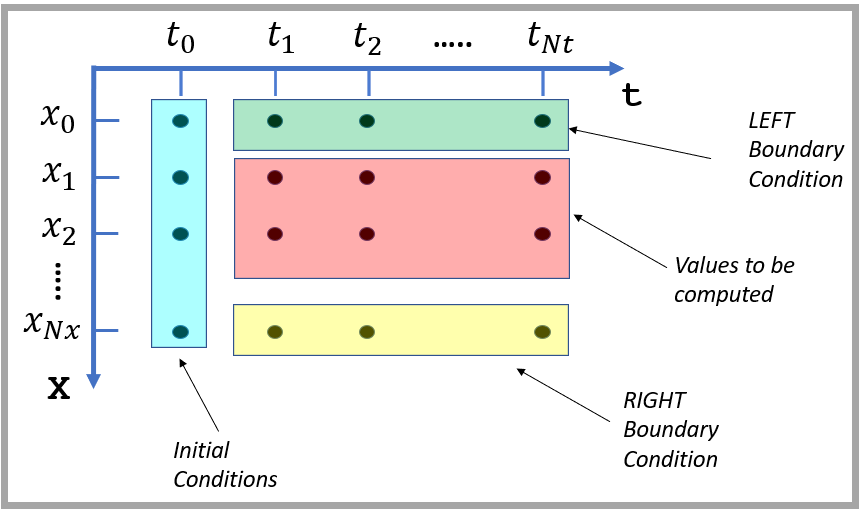

T             = zeros(Npt, Ntime_pts); % preallocate with ALL zeros
T(  :, 1)     = IC_Tz( x(:) );         % INITIAL conditions

T(  1, 2:end) = BC_T0(0);              % LEFT  Boundary condition
T(Npt, 2:end) = BC_TL(0);              % RIGHT Boundary condition

#### Do the Time stepping   

A = A_TAB{:,:};
t = zeros(Ntime_pts, 1);

for ll = 1:n_time_intervals % counts instances in time    
        
    % for each time instance we need to assemble a rhs
    rhs              = T(:, ll); 
    
     T_at_ll_plus_1  = A\rhs;   
     
     T(:, ll + 1) = T_at_ll_plus_1;         
     t(ll + 1)    = t(ll) + dt;
end

## Visualize the solution - Part 1

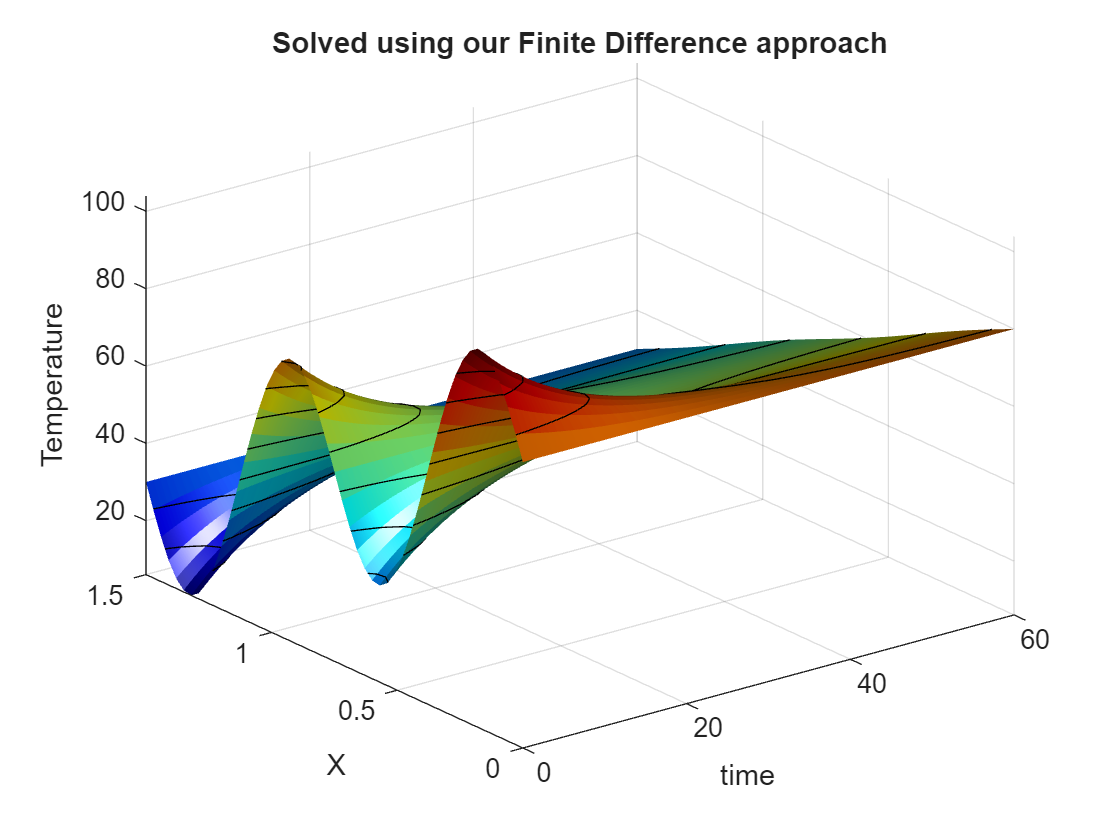

figure; 
    surf( t, x, T, 'EdgeColor',"none");  
        xlabel('time');   ylabel('X');  zlabel("Temperature");
        camlight('headlight')
        axis("tight")
        colormap(jet)
    hold("on")
        contour3(gca,  t, x, T, 10, '-k') 
         title("Solved using our Finite Difference approach")

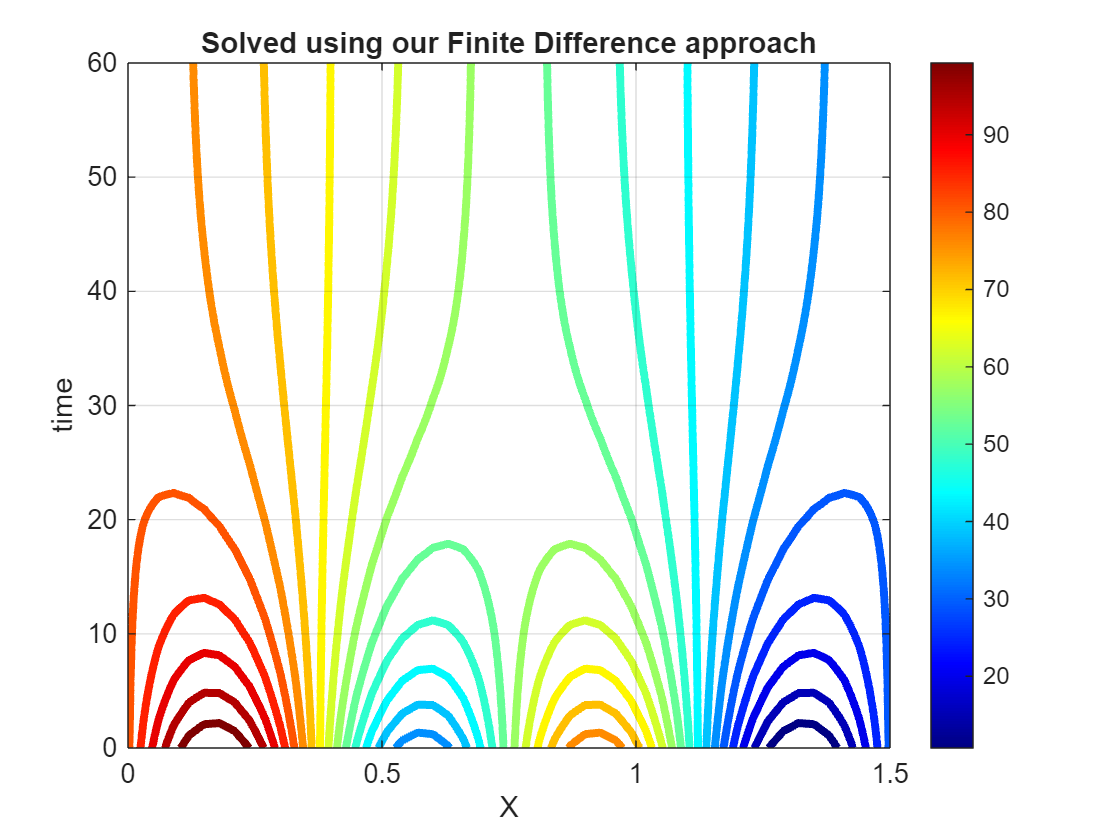

            
figure;
    [~, c_props] = contour(x, t, T', 20); % ATTENTION:  NOTE the order and the transpose !!!!
        c_props.LineWidth = 3;
        xlabel("X");  ylabel("time");  zlabel("Temperature"); grid("on")
        colormap(jet)
        colorbar  
        title("Solved using our Finite Difference approach")  

And we can animate the solution as well:

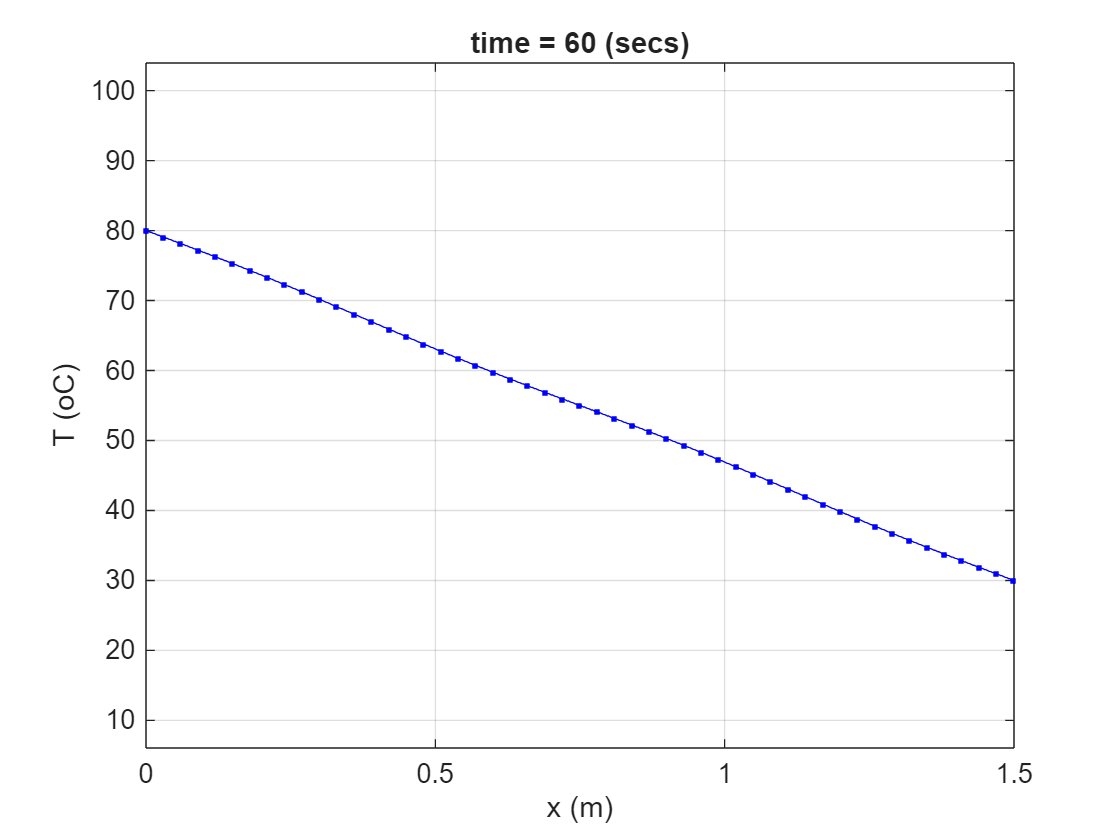

figure;
    LOC_animate_solution(t, x, T, animation_plot_interval);

To reduce the computational cost of showing the animation, increase the `animation_plot_interval` variable to create fewer number of frames. 

# Slice and Dice

 **ATTENTION:**  you will need to click the "**CLICK ME to UPDATE**" button before the plot will update to reflect any changes that you have made in the analysis section above, Eg: if you experiment with the number of spatial intervals ... you will then need to CLICK the button ...  before the results of the NEW analysis are displayed. 

Let's drag a "cutting" plane along the TIME axis and plot the temperature $T\left(x,\;t=\textrm{constant}\right)$

t_norm = 0.263;

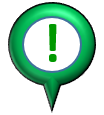 **NOTE:  **the slider bar represents "normalised time", i.e.: 

- $\Longrightarrow$` t_norm = 1`  , corresponds to $t=t_{\textrm{MAX}}$

- $\Longrightarrow$` t_norm = 0`  , corresponds to $t=t_{\textrm{MIN}}$

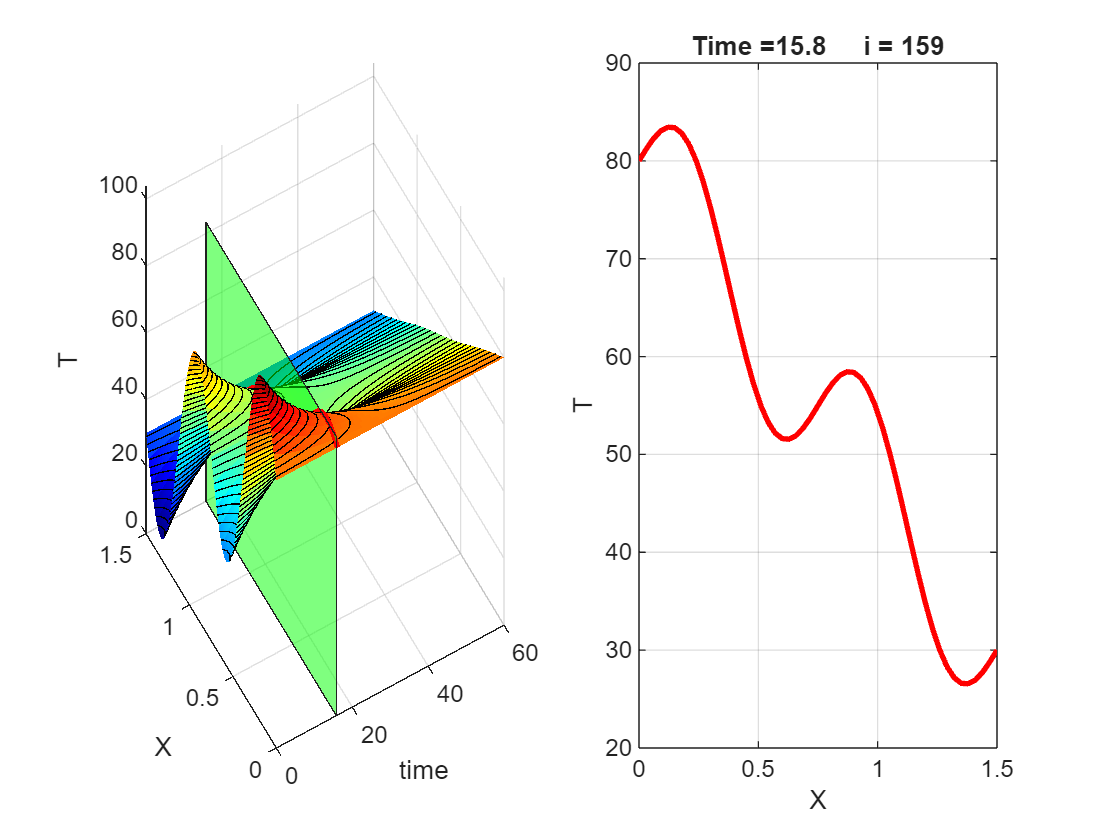

LOC_slice_and_dice(T, t, x, t_norm)

# **Extra credit:**  solve using the PDE toolbox

We can solve this same problem using the [**PDE Toolbox**](matlab:  web(fullfile(docroot, 'pde/index.html'))) to solve a 2D Thermal Analysis problem.

- 
$$k\ldotp \frac{\partial^{\;2} T}{\partial x^2 }\;\;\;=\;\frac{\partial T}{\partial t}$$


## **Create a Transient Thermal model**

thermalmodel = createpde('thermal','transient');

## Define the geometry

Define the geometry of our system using the  [`decsg`](matlab:  doc decsg) function

gdm_COL = [3 4   0      L   L      0 ...
                 0      0   (L/5)  (L/5)  ]';
ns      = ['R1A']'; 
g       = decsg(gdm_COL,'R1A',ns);

This geometry gets "absorbed" into our thermal model by using the  [`geometryFromEdges`](matlab:  doc geometryFromEdges)() function:

geometryFromEdges(thermalmodel,g);

## Visualize the geometry

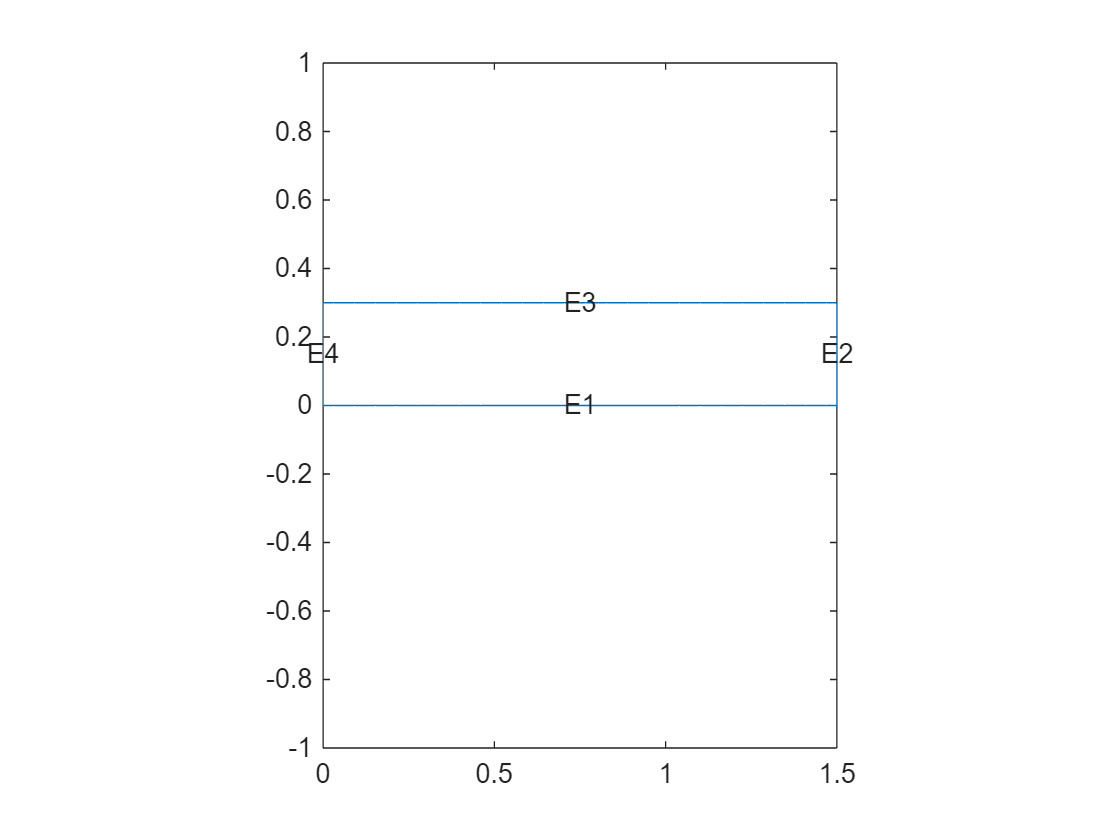

figure;
    pdegplot(thermalmodel,'EdgeLabels','on')
        ylim([-1,1])
        axis equal

## Specify Thermal Properties of the Material

Specify the thermal conductivity, mass density, and specific heat of the material.

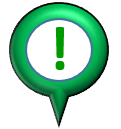RECALL**:    **$\alpha \;\;=\;1\;=\;\frac{k}{\rho \;\ldotp c_P }\;\;\;\;\left\lbrack \frac{m^2 }{\sec }\right\rbrack$     where:     $k\;\;\left\lbrack \frac{W}{m\ldotp K}\right\rbrack$     and     $\rho \;\;\left\lbrack \frac{\textrm{kg}}{m^3 }\right\rbrack$     and     $c_P \;\;\left\lbrack \frac{J}{\textrm{kg}\ldotp K}\right\rbrack$    

thermalProperties(thermalmodel, 'ThermalConductivity',K,...
                                'MassDensity',        1,...
                                'SpecificHeat',       1);

## Set the Boundary conditions

Next we need to set the 4 boundary conditions of the rod.  To do this we use the EDGE labels displayed by the [`pdegplot`](matlab:  web(fullfile(docroot, 'pde/ug/pdegplot.html')))

thermalBC(thermalmodel,'Edge',1, 'HeatFlux',0); % NO heat transfer in the Y direction at the BOTTOM
thermalBC(thermalmodel,'Edge',3, 'HeatFlux',0); % NO heat transfer in the Y direction at the TOP
thermalBC(thermalmodel,'Edge',4, 'Temperature',BC_T0(0));  % LEFT  side BC 
thermalBC(thermalmodel,'Edge',2, 'Temperature',BC_TL(0));  % RIGHT side BC 

## Set Initial Conditions

Set the initial temperature value across the ROD:.

T0      = @(location) IC_Tz(location.x);

thermalIC(thermalmodel, T0);

## Generate Mesh

Create and plot a mesh.

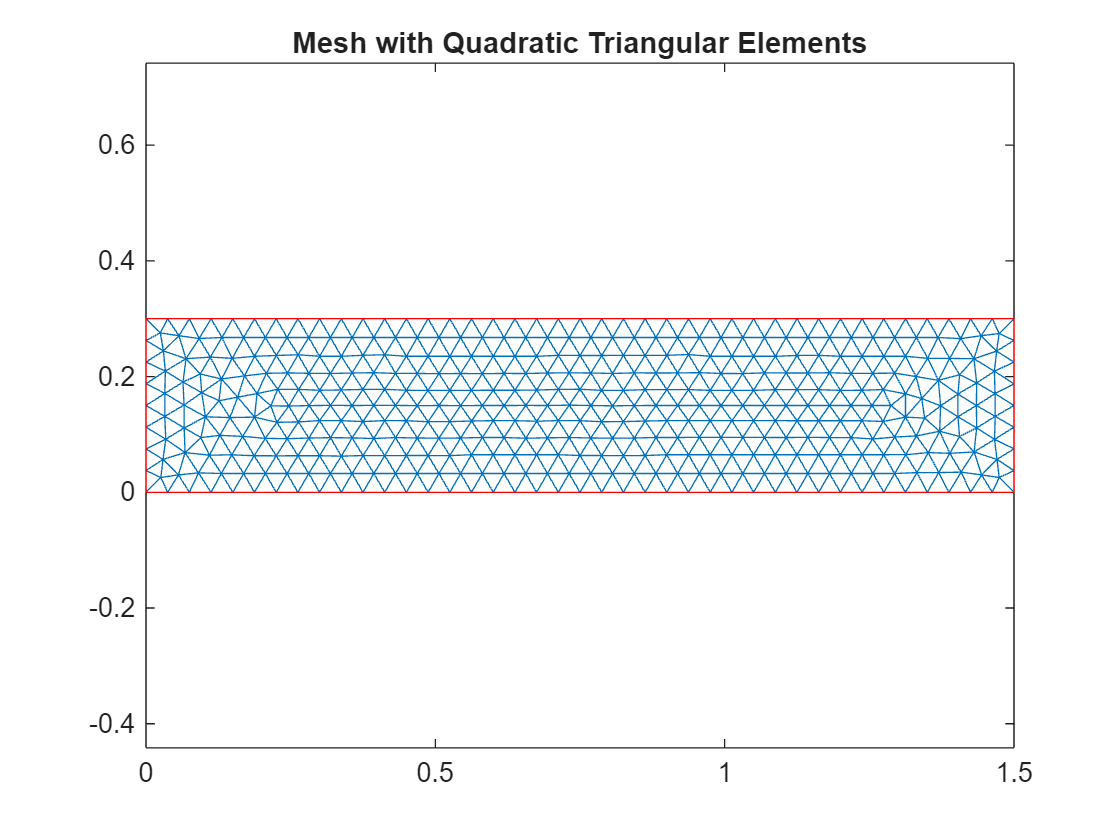

generateMesh(thermalmodel, "Hmax", L/40);

figure
    pdemesh(thermalmodel)
        title('Mesh with Quadratic Triangular Elements')

## Calculate Solution

Use the `solve` function to calculate the solution.

tlist = dt*[0:n_time_intervals];
thermalresults = solve(thermalmodel,tlist)

thermalresults =   TransientThermalResults with properties:

      Temperature: [1669×601 double]
    SolutionTimes: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000 2 2.1000 2.2000 2.3000 2.4000 2.5000 2.6000 2.7000 2.8000 2.9000 3 3.1000 3.2000 … ] (1×601 double)
       XGradients: [1669×601 double]
       YGradients: [1669×601 double]
       ZGradients: []
             Mesh: [1×1 FEMesh]


## Visualize the Transient response

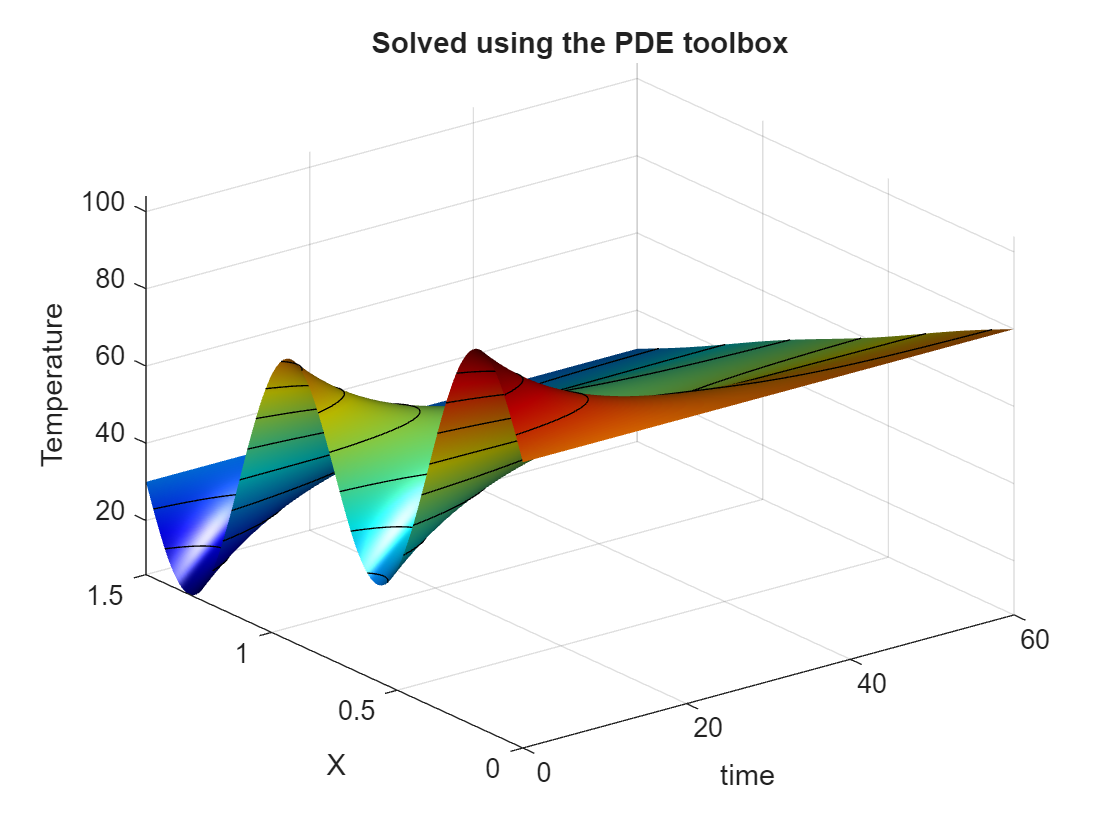

my_x_list  = 0:0.001:L;
my_y_list = zeros(size(my_x_list));
my_t_list = thermalresults.SolutionTimes;

Tintrp    = interpolateTemperature( thermalresults, ...
                                     my_x_list, my_y_list, 1:length(my_t_list) );

% plot the 3D surface
figure;
    
    surf( my_t_list, my_x_list, Tintrp, 'EdgeColor',"none");  
        xlabel('time');   ylabel('X');  zlabel("Temperature");
        camlight('headlight')
        axis("tight")
        colormap(jet)
    hold("on")
        contour3(gca,  my_t_list, my_x_list, Tintrp, 10, '-k') 
        title("Solved using the PDE toolbox")

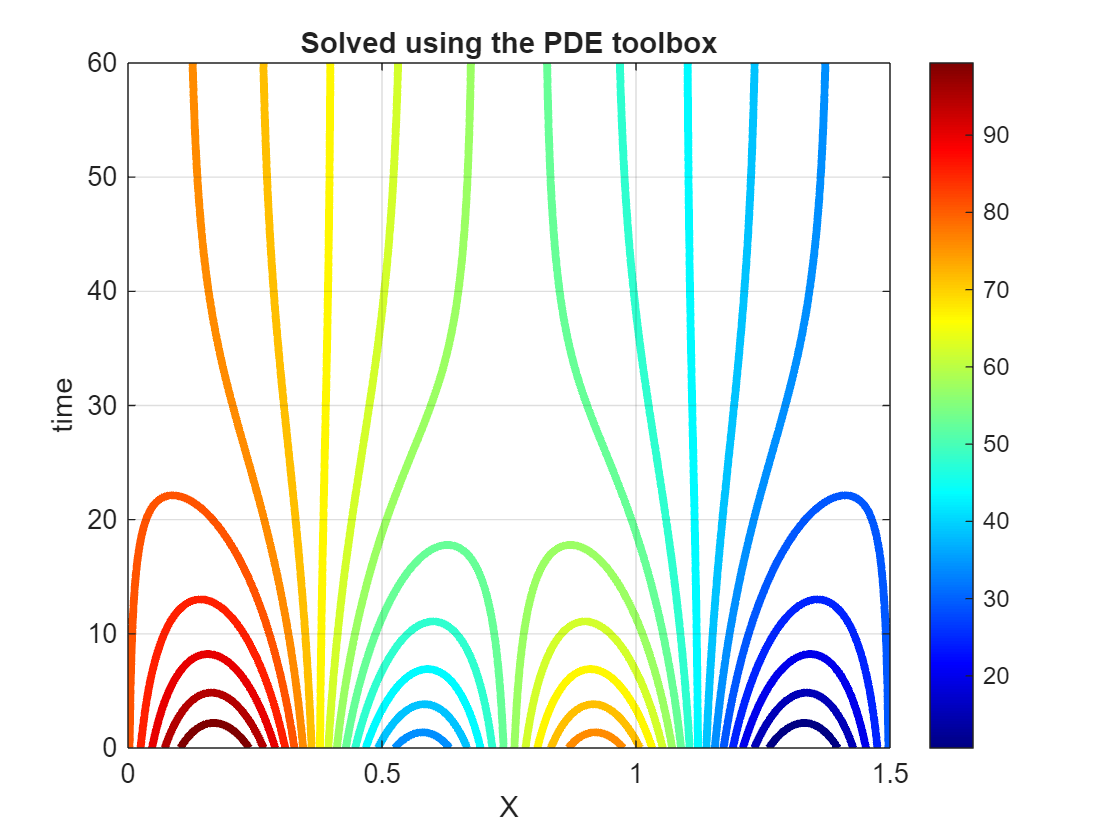

            
figure;
    [~, c_props] = contour(my_x_list, my_t_list, Tintrp', 20); % ATTENTION:  NOTE the order and the transpose !!!!
        c_props.LineWidth = 3;
        xlabel("X");  ylabel("time");  zlabel("Temperature"); grid("on")
        colormap(jet)
        colorbar 
        title("Solved using the PDE toolbox")

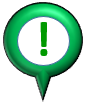**ATTENTION:**  These results look very similar to the ones that we computed using our own Finite Difference implementation

# Local Subfunctions only beyond this point

**Slice and Dice:**

function LOC_slice_and_dice(U, t, x, t_norm)

    kk_t   = 1 +  round(t_norm*(-1+length(t)));

    t_val = t(kk_t);   
    U_vec = U(:, kk_t);
    x_vec = x;
      
    % set up figure and the 2 axes
    figure;
    hax(1) = subplot(1,2,1);
    hax(2) = subplot(1,2,2);
   
    % plot the U vs X slice
    plot(hax(2), x_vec, U_vec, '-r', 'LineWidth', 2);
    grid(hax(2), 'on');
    xlabel(hax(2),'X'); ylabel(hax(2),'T');
    title(hax(2), ("Time =" + t_val+"     i = " + kk_t))
    
    
    % plot the 3D surface
    hAX = hax(1);
    surf(hAX, t,  x, U, 'EdgeColor','none');
    %surf(hAX, t,  x, U, 'EdgeColor','k', 'MeshStyle','row');
        xlabel(hAX,'time');
        ylabel(hAX, 'X');
        zlabel(hAX, 'T');
        %lightangle(75, 70)
        hold(hAX,'on');
        contour3(hAX,  t, x, U, 50, '-k') 
        view(hAX,[-29.8 35.4])
        colormap(jet)
       
    % plot the slice plane
    xp = [t_val, t_val, t_val, t_val ];
    yp = [x_vec(1), x_vec(end), x_vec(end), x_vec(1) ];
    zp = [0,0,max(U_vec), max(U_vec)];
    patch(hAX, xp,yp,zp, 'g', 'FaceAlpha', 0.5);
    
    t_vec = t_val*ones(size(x_vec));
    plot3(hAX,t_vec,x_vec,U_vec, '-r', 'LineWidth',3)
end

Animate our Finite Difference solution:

function LOC_animate_solution(t, x, T, plot_interval)
    
    hf = gcf;
    
    [Nx, Nt] = size(T);
    
    hL = plot(x, T(:,1), ".b-");
        grid("on")
        ylim([min(T(:)), max(T(:))]);    
        xlim([min(x), max(x)  ]);

        xlabel("x (m)");
        ylabel("T (oC)");
        title("time = "+t(1)+" (secs)");

    for tt=2:Nt    
        if (mod(tt,plot_interval)==0 || tt==Nt)
            hL.YData = T(:,tt);
    
            title("time = "+t(tt)+" (secs)","FontWeight","bold");
            drawnow
        end % if
    end  % for

end